# Práctica 2 - Modelos Probabilísticos,

# Filtros Discretos y Filtros de Partículas - Rodríguez, Maximiliano

## 1: Muestreo de distribuciones de probabilidad

Se pidió implementar 3 funciones que generaran muestras normales que reciban como parámetros algún $\mu$ y $\sigma$, para luego compararlas entre sí. Además, en la implementación se agregó que se pueda modificar el largo de muestras $n$.

### Normal a partir de 12 uniformes

Para generar estas muestras, se generaron 12 normales en el rango $\left\lbrack -\sigma \;;\sigma \;\right\rbrack$. Luego se sumaron los valores y se los dividió a la mitad. Finalmente, se sumó el valor de la esperanza requerida.


function z = normal_con_uniformes(mu, sigma, n)
    r = -sigma + (2*sigma) .* rand(12, n);
    z = (1/2)* sum(r);
    z =  z + mu;
end

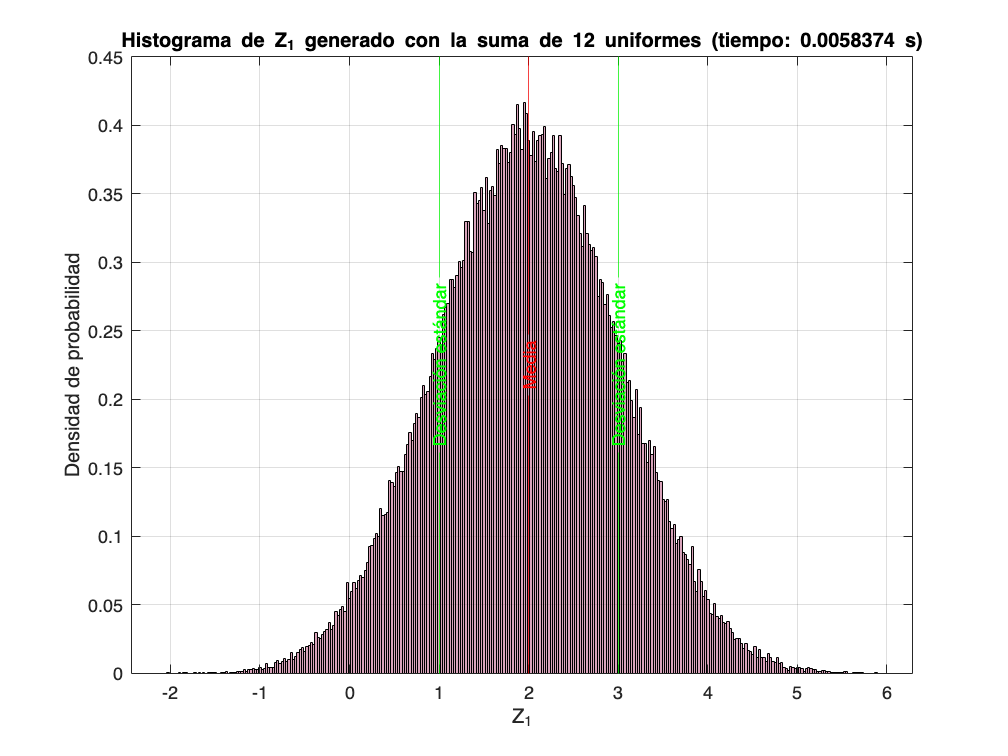

n = 1e5;

bines = ceil(sqrt(n));

mu = 2;
sigma = 1;
tic;
Z1 = normal_con_uniformes(mu, sigma, n);
tiempo1 = toc;
figure();
histogram(Z1, bines, 'Normalization', 'pdf', 'FaceColor', '#c0688d');
hold on
title('Histograma de Z_1 generado con la suma de 12 uniformes (tiempo: ' + string(tiempo1) + ' s)');
xlabel('Z_1');
ylabel('Densidad de probabilidad')

xline(mu, 'r', 'Media', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu + sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu - sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
grid on
hold off

### Muestreo con rechazo

Para muestrear con rechazo se propuso un valor `x` aleatorio en el intervalo $\left\lbrack \mu -5\sigma \;;\mu +5\sigma \;\right\rbrack$ (que es donde prácticamente toda la distribución normal tiene masa de probabilidad). Luego, se evaluó la densidad f(x) en ese punto usando la función `normpdf`. Se generó un número aleatorio `c` entre 0 y el máximo de la densidad normal (que es $\frac{1}{\sqrt{\;2\pi \;\sigma {\;}^{2\;} }}$). Si `c` es menor o igual a f(x), el valor `x` es aceptado como muestra. Si no, se rechaza `x` y se vuelve a intentar.

Así hasta completar las `n` muestras.

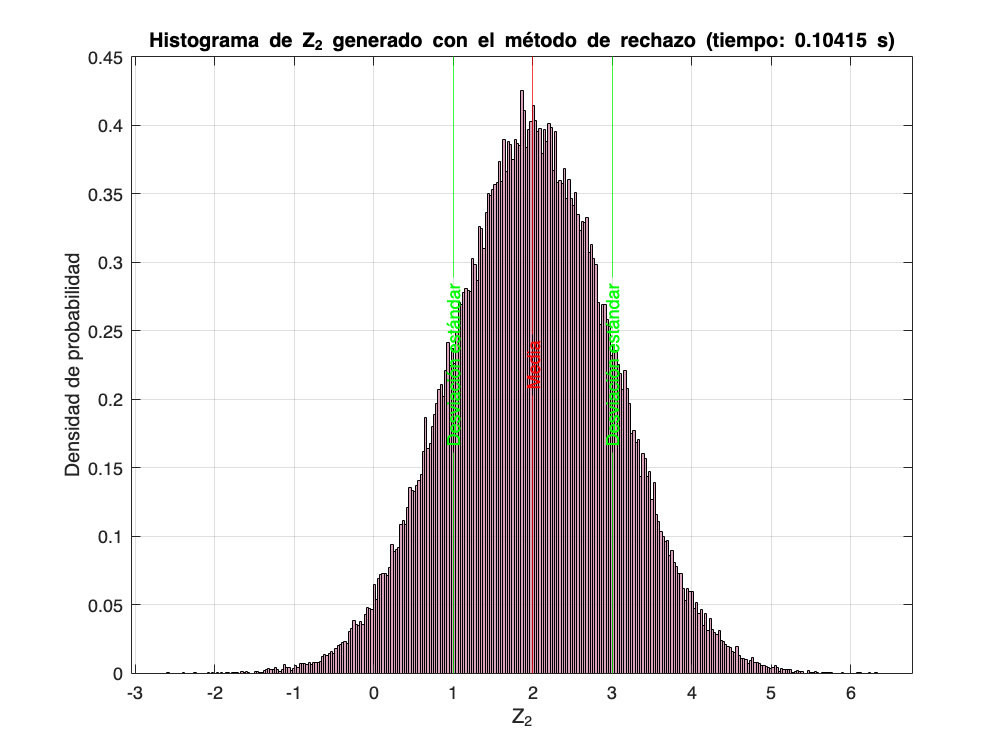

function z = normal_muestra_con_rechazo(mu, sigma, n)
    z = zeros(1, n);
    for i = 1:n
        aprobado = 0;
        while aprobado == 0
            x = mu - 5*sigma + (10*sigma) * rand();
            f_x = normpdf(x, mu, sigma);
            c = 1/(sqrt(2*pi)*sigma) * rand(1, 1);
            if c <= f_x
                z(i) = x;
                aprobado = 1;
            end
        end

    end
end

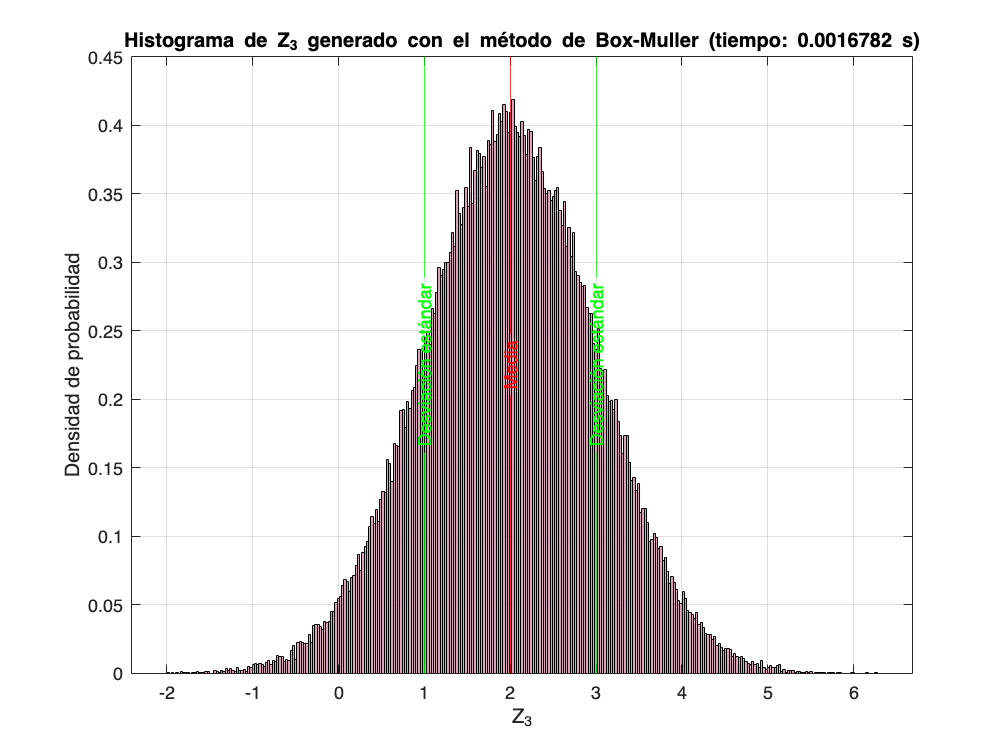

tic;
Z2 = normal_muestra_con_rechazo(mu, sigma, n);
tiempo2 = toc;
figure;
histogram(Z2, bines, 'Normalization', 'pdf', 'FaceColor', '#c0688d');
hold on
title('Histograma de Z_2 generado con el método de rechazo (tiempo: ' + string(tiempo2) + ' s)');
xlabel('Z_2');
ylabel('Densidad de probabilidad')
xline(mu, 'r', 'Media', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu + sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu - sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
grid on

### Transformación de Box-Muller

Esta transformación consiste en que mediante dos uniformes [0,1], se puede conseguir una normal estándar con la siguiente ecuacion:


$$x=\cos \left(2\pi u_1 \right)\cdot \sqrt{-\ln \left(u_2 \right)}$$


Luego, mediante la transformación afín:


$$z=\mu +\sigma \cdot x$$


Se consiguió una $\mathcal{N}\left(\mu ,\sigma \right)$.

function z = normal_box_muller(mu, sigma, n)
    u1 = rand(n, 1);
    u2 = rand(n, 1);
    z = mu + sigma * sqrt(-2*log(u1)) .* cos(2*pi*u2);
end

tic;
Z3 = normal_box_muller(mu, sigma, n);
tiempo3 = toc;
figure;
histogram(Z3, bines, 'Normalization', 'pdf', 'FaceColor', '#c0688d');
hold on
title('Histograma de Z_3 generado con el método de Box-Muller (tiempo: ' + string(tiempo3) + ' s)');
xlabel('Z_3');
ylabel('Densidad de probabilidad');
xline(mu, 'r', 'Media', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu + sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
xline(mu - sigma, 'g', 'Desviación estándar', 'LabelVerticalAlignment', 'middle', 'LabelHorizontalAlignment', 'center');
grid on

Se observó que el método más rápido es la transformación de Box-Muller.

## **2: Modelo de Odometría con Ruido**

Para la función `odometria` se implementó un modelo de movimiento para un robot basado en la información de odometría, incorporando incertidumbre en las acciones. A partir de una posición inicial $x=\left(x,y,\theta \;\right)$ y un comando de movimiento $u=\left(\delta_{\textrm{rot1}} ,\delta_{\textrm{rot2}} \;,\delta_{\textrm{trans}} \right)$ se calculó una nueva pose estimada.

Primero, se extrajeron las tres componentes del movimiento:

- $\delta_{\textrm{rot1}}$: la primera rotación (antes de avanzar),

- $\delta_{\textrm{rot2}}$: la segunda rotación (después de avanzar),

- $\delta_{\mathrm{trans}}$: la distancia de traslación.

A cada una de estas componentes se les agregó ruido, modelado como ruido gaussiano de media cero y varianza dependiente de los parámetros de error α y de la magnitud de los movimientos. Este ruido fue generado usando la función `normal_box_muller`, que simulaba ruido normal.

Finalmente, la nueva posición (x′,y′,θ′) del robot se calculó actualizando el estado inicial según el movimiento ruidoso.

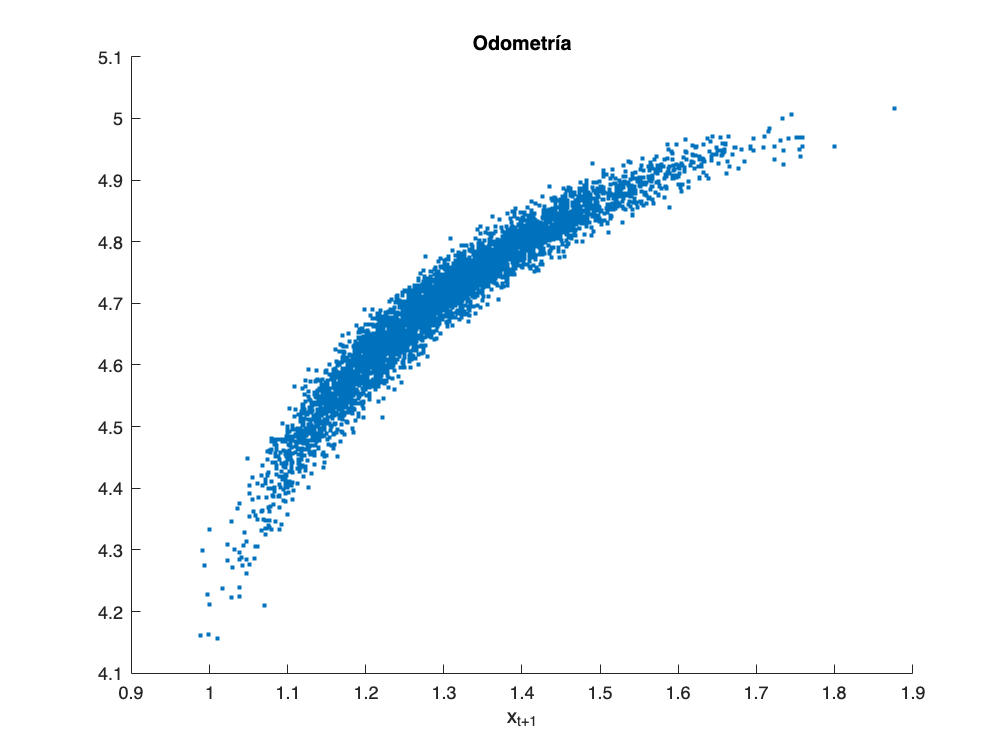

function x_t_mas_1 = odometria(x, u, alpha)

    % Extraer componentes
    delta_rot1 = u(1);
    delta_rot2 = u(2);
    delta_trans = u(3);

    % Agregar ruido a cada componente
    delta_rot1_hat = delta_rot1 + normal_box_muller(0, (alpha(1)*abs(delta_rot1) + alpha(2)*delta_trans), 1);
    delta_trans_hat = delta_trans + normal_box_muller(0, (alpha(3)*delta_trans + alpha(4)*(abs(delta_rot1) + abs(delta_rot2))), 1);
    delta_rot2_hat = delta_rot2 + normal_box_muller(0, (alpha(1)*abs(delta_rot2) + alpha(2)*delta_trans), 1);

    % Calcular nueva pose
    x_t_mas_1 = zeros(3, 1);
    x_t_mas_1(1) = x(1) + delta_trans_hat * cos(x(3) + delta_rot1_hat);
    x_t_mas_1(2) = x(2) + delta_trans_hat * sin(x(3) + delta_rot1_hat);
    x_t_mas_1(3) = x(3) + delta_rot1_hat + delta_rot2_hat;
end

Se evaluó el modelo de la siguiente forma:

n = 5000;

x_t = [2; 4; pi/2];
u_t = [pi/4; 0; 1];

alpha = [0.1; 0.1; 0.01; 0.01];

x_t_mas_1 = zeros(3, n);

for i = 1:n
    % Calcular la odometría
    x_t_mas_1(:, i) = odometria(x_t, u_t, alpha);
end

figure;
hold on
title('Odometría')
xlabel('x_{t+1}');
scatter(x_t_mas_1(1, :), x_t_mas_1(2, :), '.')

## 3: Filtro discreto

**Implementación del Filtro de Bayes (Paso de Predicción)**

Para la función `bayes_filter` se implementó el paso de predicción del filtro de Bayes discreto para localización de un robot. Dados el belief actual sobre el estado belief_actual(x) y una acción accion realizada por el robot, se calculó una nueva distribución de probabilidad belief_nuevo(x) sobre los estados posibles.

El procedimiento consistió en:

- Inicializar el belief nuevo como un vector de ceros.

- Para cada estado posible x, se sumó la probabilidad de todas las transiciones posibles desde los estados anteriores xant, ponderada por la creencia anterior en $x_{\mathrm{ant}} \;$y la probabilidad de transición $p\left(x|x_{\mathrm{ant}} \;,\mathrm{accion}\right)$, dada por la función `transicion`.

- Finalmente, el belief nuevo se normalizó para asegurarse de que la suma total de probabilidades fuera igual a 1.

De esta forma, la función actualizó la estimación de la posición del robot teniendo en cuenta únicamente el modelo de movimiento.

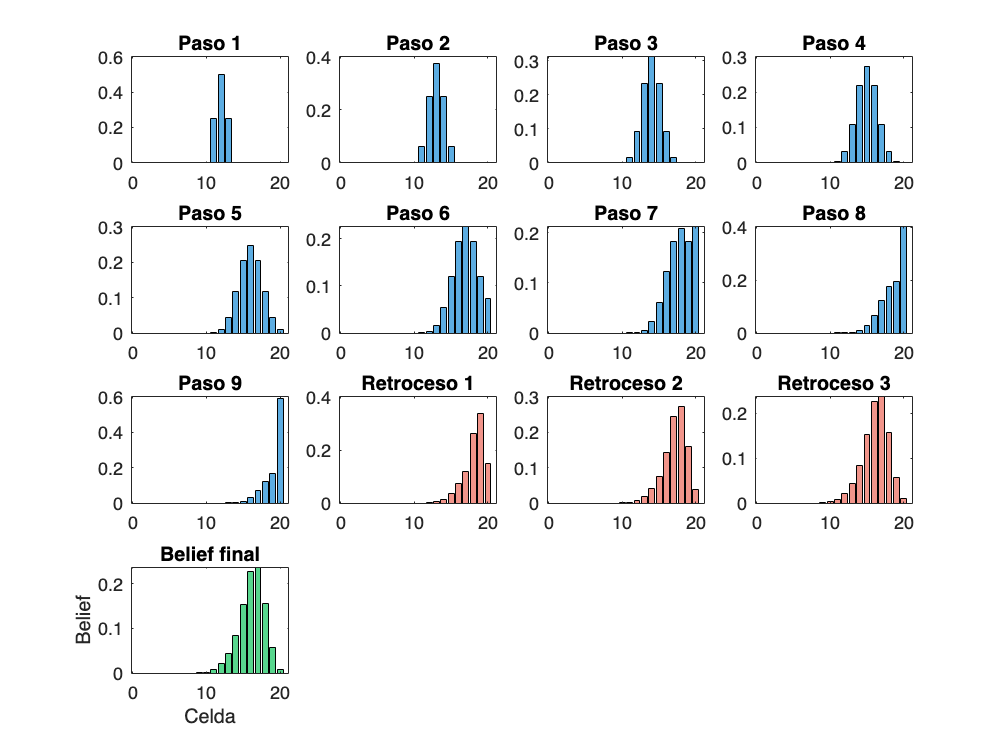

function belief_nuevo = bayes_filter(belief_actual, accion)
    n = length(belief_actual);
    belief_nuevo = zeros(n, 1);

    for x = 1:n

        for x_ant = 1:n
            p = transicion(x_ant, x, accion);
            belief_nuevo(x) = belief_nuevo(x) + p * belief_actual(x_ant);
        end
    end

    % Normalización
    belief_nuevo = belief_nuevo / sum(belief_nuevo);
end

Para la función `transicion, se` modeló la probabilidad de pasar de un estado anterior $x_{\textrm{ant}} \;$a un estado actual $x$, dado que el robot realizó una determinada acción accionaccion. El entorno considerado fue un mundo discreto de n=20 celdas.

Se implementaron dos tipos de acciones:

- Acción 1: moverse hacia la derecha.

- Acción -1: moverse hacia la izquierda.

El comportamiento de transición incorporó incertidumbre en el movimiento:

- Al intentar moverse a la derecha, el robot podía:

- Llegar correctamente a la celda siguiente ($x=x_{\textrm{ant}} +1$) con probabilidad 0.5,

- Quedarse en la misma celda ($x=x_{\textrm{ant}}$) o avanzar dos celdas ($x=x_{\textrm{ant}} +2$) con probabilidad 0.25 cada una.

- En los bordes (por ejemplo, en la celda 20), el robot permanecía en su posición con probabilidad 1, para evitar salir del mundo.

De manera análoga, para moverse a la izquierda:

- El robot tenía 0.5 de probabilidad de moverse a la celda anterior ($x=x_{\textrm{ant}} -1$),

- 0.25 de quedarse o de retroceder dos celdas,

- En la celda 1, quedaba fijo con probabilidad 1.

function transicion = transicion(x_ant, x, accion)

Reading world data ... done
Reading sensor data ... done
..........................................................................................................................................................................................................................................................................................................................................Final pose:     5.0471    4.8511   -4.6946



    transicion = 0; % Inicializar en cero
    n = 20; % Número de celdas del mundo

    if accion == 1 % moverse a la derecha
        if x_ant == n
            if x == n
                transicion = 1.0;
            end
        elseif x_ant == n-1
            if x == n-1
                transicion = 0.25;
            elseif x == n
                transicion = 0.75;
            end
        else
            if x == x_ant
                transicion = 0.25;
            elseif x == x_ant + 1
                transicion = 0.5;
            elseif x == x_ant + 2
                transicion = 0.25;
            end
        end
    elseif accion == -1 % moverse a la izquierda
        if x_ant == 1
            if x == 1
                transicion = 1.0;
            end
        elseif x_ant == 2
            if x == 1
                transicion = 0.75;
            elseif x == 2
                transicion = 0.25;
            end
        else
            if x == x_ant
                transicion = 0.25;
            elseif x == x_ant - 1
                transicion = 0.5;
            elseif x == x_ant - 2
                transicion = 0.25;
            end
        end
    end
end

Se ejecutó 9 comandos consecutivos de ‘avanzar un paso’ y luego 3 comandos de ‘retroceder un paso’. Luego, se graficó el belief resultante de la posición del

robot. Se comenzó con el belief inicial de `bel=[zeros(10; 1); 1; zeros(9; 1)].`

% Definir número de celdas
n_celdas = 20;

% Belief inicial: el robot está en la celda 11
bel = [zeros(10, 1); 1; zeros(9, 1)];

% Crear figura
figure;
tiledlayout(4, 4, 'TileSpacing', 'compact');

% Ejecutar 9 comandos de avanzar (+1)
for i = 1:9
    bel = bayes_filter(bel, 1);
    nexttile
    bar(1:n_celdas, bel, 'FaceColor', '#5DADE2');
    title(['Paso ', num2str(i)]);
end

% Luego, 3 comandos de retroceder (-1)
for i = 1:3
    bel = bayes_filter(bel, -1);
    nexttile
    bar(1:n_celdas, bel, 'FaceColor', '#F1948A');
    title(['Retroceso ', num2str(i)]);
end

% Último subplot: belief final
nexttile
bar(1:n_celdas, bel, 'FaceColor', '#58D68D');
title('Belief final');
xlabel('Celda');
ylabel('Belief');

## 4: Filtros de partículas

Se implementó un filtro de partículas basándose en una estructura de código provista por la cátedra.

Para la función `measurement_model` se implementó el modelo de observación para un filtro de partículas utilizando un sensor que mide únicamente distancia. Su objetivo fue calcular los **pesos de cada partícula** en base a qué tan bien sus predicciones coincidieron con las observaciones del robot.

Los argumentos de entrada fueron:

- `z`: lista de observaciones, cada una con el `id` del landmark y la distancia (`range`) medida,

- `x`: matriz con la posición de cada partícula en forma (x,y,θ),

- `l`: estructura con las posiciones reales de los landmarks.

Para cada observación:

- Se recuperó la posición real del landmark observado.

- Se calculó la distancia esperada desde cada partícula hasta ese landmark.

- Se comparó esa distancia con la distancia medida por el sensor.

- Se evaluó una función de verosimilitud gaussiana (de media cero y desviación σ=0.2σ=0.2) para asignar una probabilidad a esa diferencia.

- El peso de cada partícula se actualizó multiplicativamente con esa probabilidad.

Finalmente, se normalizaron los pesos para que la suma total fuera 1, manteniendo así una distribución de probabilidad válida.


function weight = measurement_model(z, x, l)
    % Computes the observation likelihood of all particles using range-only sensor model.
    %
    % z: array of landmark observations with fields .id and .range
    % x: Nx3 matrix of particles (x, y, theta)
    % l: array of landmarks with fields .id, .x, .y
    
    sigma = 0.2;
    N = size(x, 1); % cantidad de partículas
    weight = ones(N, 1); % inicializar pesos

    if isempty(z)
        return;
    end
    
    for i = 1:length(z)
        % Obtener posición del landmark observado
        landmark_position = [l(z(i).id).x, l(z(i).id).y];
        measurement_range = z(i).range;
        
        % Calcular la distancia esperada desde cada partícula al landmark
        dx = x(:,1) - landmark_position(1);
        dy = x(:,2) - landmark_position(2);
        expected_range = sqrt(dx.^2 + dy.^2);
        
        % Likelihood gaussiana
        likelihood = exp(-0.5 * ((expected_range - measurement_range) / sigma).^2);
        
        % Acumular peso
        weight = weight .* likelihood;
    end

    % Normalizar (opcional, pero común)
    weight = weight / sum(weight);
end

**Remuestreo por Muestreo Estocástico Universal**

La función `resample` aplicó el algoritmo de **muestreo estocástico universal** para seleccionar un nuevo conjunto de$M$partículas a partir de un conjunto ponderado. Cada partícula $x_i$ tenía un peso $w_i$, con $\sum_{i=1}^M w_{i\;} =1$.

Este método distribuyó M muestras equiespaciadas en el intervalo [0,1), comenzando desde un punto aleatorio $r\sim \mathcal{U}\left(0,\frac{1}{M}\right)$. Luego se construyeron los puntos: $U_m =r+\frac{\;m-1}{M},m=1,\ldotp \ldotp \ldotp M\ldotp$

Con una variable acumulada c (que representa $\sum_{j=1}^i w_j$) se determinó para cada $U_m \;$el índice i tal que:


$$\sum_{j=1}^{i-1} w_j <U_m \le \sum_{j=1}^{i-1} w_j$$


y se seleccionó la partícula $x_i$.

function new_particles = resample(particles, weights)
    % Performs stochastic universal sampling from a weighted particle set.
    %
    % particles: M x D matrix where each row is a particle
    % weights: M x 1 vector of normalized weights
    
    M = size(particles, 1);
    new_particles = zeros(size(particles));
    
    % Asegurarse de que los pesos estén normalizados
    weights = weights / sum(weights);
    
    % Inicialización
    r = rand() / M; % primer índice aleatorio
    c = weights(1);
    i = 1;
    
    % Remuestreo
    for m = 1:M
        U = r + (m - 1) / M;
        while U > c
            i = i + 1;
            c = c + weights(i);
        end
        new_particles(m, :) = particles(i, :);
    end
end

## Visualización

Se elegió una sola hipótesis del conjunto de partículas del filtro para representar la posición del robot.Se implementó la función `mean_position `que se usó para graficar la pose del robot.

function mean_pos = mean_position(particles, weights)
    weights = weights / sum(weights);

    mean_pos = sum(particles .* weights, 1);
end

Luego, se ejecuta el `particle_filter.m`

`Para observar el movimiento, se recomienda usar el TP2.html`

particle_filter